# **MATLAB Live Script that loads in the raw data of the Yeh-Lindau photoionisation cross-sections and saves them all as a concise MATLAB data structure**

The **Photoionisation Cross-Section and Asymmetry Database (PIXSAD) **local MATLAB reference file 'PIXSAD_PCC.mat' is created and saved here.

- You do not need to run this program, as the database will always be up-to-date with all released versions.

- This MATLAB Live Script is saved and stored here for future reference and in case of any future updates to the PIXSAD database.

The photoionisation cross-section and asymmetry parameter data is taken from two references;

- [1] [https://vuo.elettra.eu/services/elements/WebElements.html](https://vuo.elettra.eu/services/elements/WebElements.html)

- [2] J.J. Yeh, I. Lindau, *Atomic subshell photoionization cross sections and asymmetry parameters: 1 ⩽ Z ⩽ 103*, Atomic Data and Nuclear Data Tables, Volume 32, Issue 1, 1985, Pages 1-155, ISSN 0092-640X, [https://doi.org/10.1016/0092-640X(85)90016-6](https://doi.org/10.1016/0092-640X(85)90016-6).

**(1)     :    Defining all of the variables**

close all; clear all;
% -- Defining the elements whose photoionisation cross-sections we have
ATOM_SYMB = {...
    'H','He',...
    'Li','Be','B','C','N','O','F','Ne',...
    'Na','Mg','Al','Si','P','S','Cl','Ar',...
    'K','Ca','Sc','Ti','V','Cr','Mn','Fe','Co','Ni','Cu','Zn','Ga','Ge','As','Se','Br','Kr',...
    'Rb','Sr','Y','Zr','Nb','Mo','Tc','Ru','Rh','Pd','Ag','Cd','In','Sn','Sb','Te','I','Xe',...
    'Cs','Ba','La','Ce','Pr','Nd','Pm','Sm','Eu','Gd','Tb','Dy','Ho','Er','Tm','Yb','Lu','Hf','Ta','W','Re','Os','Ir','Pt','Au','Hg','Tl','Pb','Bi','Po','At','Rn',...
    'Fr','Ra','Ac','Th','Pa','U','Np','Pu','Am','Cm','Bk','Cf','Es','Fm','Md','No','Lr'};
% -- Defining the Z number for each one of these elements
ATOM_ZNUM = 1:length(ATOM_SYMB);
% -- Defining all of the core-levels that are probed
% --- Defining in terms of orbital notation
ATOM_CLEVEL0 = {...
    '1s',...
    '2s', '2p',...
    '3s', '3p', '3d',...
    '4s', '4p', '4d', '4f',...
    '5s', '5p', '5d', '5f',...
    '6s', '6p', '6d',...
    '7s',...
    };
% --- Defining in terms of IUPAC notation
ATOM_CLEVEL1 = {...
    'K',...                             % 1s
    'L1', 'L23',...                     % 2s, 2p
    'M1', 'M23', 'M45',...              % 3s, 3p, 3d
    'N1', 'N23', 'N45', 'N67',...       % 4s, 4p, 4d, 4f
    'O1', 'O23', 'O45', 'O67',...       % 5s, 5p, 5d, 5f
    'P1', 'P23', 'P45',...              % 6s, 6p, 6d
    'Q1',...                            % 7s
    };

**(2)     :    Iterating through all the data-files and storing the data**

% -- Path to the folders
output_path = "D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Cronus\MaterialsDatabase_PCC\Photoionisation Cross-Section and Asymmetry Database (PIXSAD)\";
path_name   = output_path + "PIXSAD_Data_YehLindau1985\";
% -- Extracting all the filenames for the photoionisation data
file_names = dir(path_name);
file_names = {file_names(~[file_names.isdir]).name};
% -- Filing through all the elements to isolate each element
for i = ATOM_ZNUM
    % --- Finding the index number for the element
    findx           = find(contains(file_names, "_"+string(ATOM_SYMB{i})+"_"));
    selected_names  = file_names(findx);
    PIXSA_FileNames{i} = selected_names;
end
% -- Loading in all the data for each text file
for i = ATOM_ZNUM
    for j = 1:length(PIXSA_FileNames{i})
        % -- Loading in all of the data
        data_00 = importdata(string(path_name) + string(PIXSA_FileNames{i}{j}));
        % -- Extracting photon energy
        hv          = data_00(:,1);
        % -- Averaging between column 2 - 4 for cross-sections (sigma)
        xsect       = mean(data_00(:,2:4), 2);
        % -- Averaging between column 5 - 7 for asymmetry factor (beta)
        asymmetry   = mean(data_00(:,5:7), 2);
        % -- Validity checks on the data for future processing
        % ---- Make sure it is in ascending order of photon energy
        [hv, indx]  = sort(hv);
        xsect       = xsect(indx);
        asymmetry   = asymmetry(indx);
        % ---- Make sure that there are no duplicates of the photon energy (only unique points)
        [hv, indx]  = unique(hv);
        xsect       = xsect(indx);
        asymmetry   = asymmetry(indx);
        % -- Storing the data into a cell array
        PIXSA_Data{i}{j} = [hv, xsect, asymmetry];
    end
end

**(3)     :    Interpolating the PIXS data onto a consistent domain**

XX = 25:1:1500; XX = XX';
% -- Loading in all the data for each text file
for i = 1:length(PIXSA_Data)
    for j = 1:length(PIXSA_Data{i})
        % -- Loading in the original data
        hv          = PIXSA_Data{i}{j}(:,1);     % -- Photon Energy
        xsect       = PIXSA_Data{i}{j}(:,2);     % -- Cross-Sections
        asymmetry   = PIXSA_Data{i}{j}(:,3);     % -- Asymmetry
        % -- Storing the data into a cell array
        xsect_V     = interp1(hv,xsect,XX,'spline');
        asymmetry_V = interp1(hv,asymmetry,XX,'spline');
        % -- Validity checks on the data for future processing
        % ---- Any data-points outside of the domain, reduce to a NaN
        [~, hv_indx(1)]	= min(abs(XX - min(hv(:))));
        [~, hv_indx(2)]	= min(abs(XX - max(hv(:))));
        xsect_V(1:hv_indx(1)) = NaN; 
        xsect_V(hv_indx(2):end) = NaN;
        asymmetry_V(1:hv_indx(1)) = NaN; 
        asymmetry_V(hv_indx(2):end) = NaN;
        % ---- Any NaN values force to zero
        xsect_V(isnan(xsect_V))         = NaN;
        asymmetry_V(isnan(asymmetry_V)) = NaN;
        % -- Appending the interpolated data into a cell array
        PIXSA_DataInterp{i}{j} = [XX, xsect_V, asymmetry_V];
    end
end

**(4)     :    Create a table for each element that sumamrises all of the PIXS data**

for i = 1:length(PIXSA_Data)
    PIXSA_Table{i}       = table();
    PIXSA_Table{i}.hv    = XX;
    for j = 1:length(PIXSA_Data{i})
        cl_name     = string(PIXSA_FileNames{i}{j}(end-6:end-5));
        xsect_name  = cl_name + "-sig";
        asymm_name  = cl_name + "-beta";
        PIXSA_Table{i}.(xsect_name) = PIXSA_DataInterp{i}{j}(:,2);
        PIXSA_Table{i}.(asymm_name) = PIXSA_DataInterp{i}{j}(:,3);
    end
end

**(5)     :    Storing the Photoionisation Cross-Section (PIXS) Data as a MATLAB structure for future reference**

PIXSAD_PCC                 = struct();
PIXSAD_PCC.ATOM_SYMB       = ATOM_SYMB;            % Atomic symbols used
PIXSAD_PCC.ATOM_ZNUM       = ATOM_ZNUM;            % Atomic Z number for each one of these elements
PIXSAD_PCC.ATOM_CLEVEL0    = ATOM_CLEVEL0;         % Cell-array of orbital notation of core-levels 
PIXSAD_PCC.ATOM_CLEVEL1    = ATOM_CLEVEL1;         % Cell-array of IUPAC notation of core-levels 
PIXSAD_PCC.FileNames       = PIXSA_FileNames;       % Cell-array of all the text file names
PIXSAD_PCC.Data            = PIXSA_Data;            % Cell-array where; {Atom Z number}{Core-level}(photon energy, xsection, asymmetry)
PIXSAD_PCC.DataInt         = PIXSA_DataInterp;      % Cell-array where; {Atom Z number}{Core-level}(photon energy, xsection, asymmetry)
PIXSAD_PCC.DataTable       = PIXSA_Table;           % MATLAB Table where; {Atom Z number}
save(char(output_path + "PIXSAD_PCC"), 'PIXSAD_PCC', '-v7.3');

# **Using 'get_pixsad_props()' to extract photoionisation cross-section and asymmetry parameters for any element / core-level**

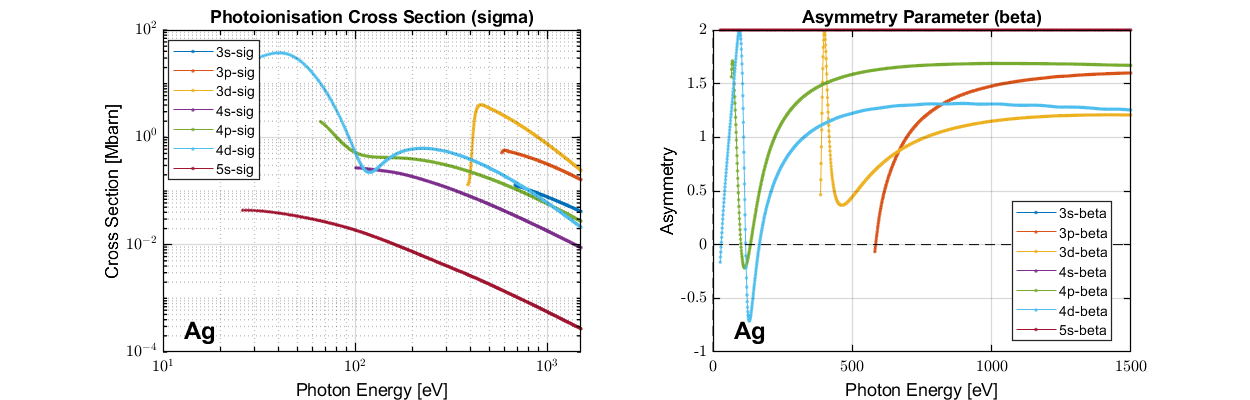

% View the PIXSA properties
view_pixsad_props('Ag');

% Using the 'get_pixsad_props()' function to extract PIXS data
[hv, xsect, asymmetry] = get_pixsad_props('Ag')

hv = 1476×1 table
    hv
    __

    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35
    36
    37
    38
    39
    40


xsect = 1476×7 table
    3s-sig    3p-sig    3d-sig    4s-sig    4p-sig    4d-sig     5s-sig 
    ______    ______    ______    ______    ______    ______    ________

     NaN       NaN       NaN       NaN       NaN         NaN         NaN
     NaN       NaN       NaN       NaN       NaN      22.876    0.043781
     NaN       NaN       NaN       NaN       NaN      24.297    0.043825
     NaN       NaN       NaN       NaN       NaN      25.729    0.043746
     NaN       NaN       NaN       NaN       NaN       27.16    0.043567
     NaN       NaN       NaN       NaN       NaN      28.577     0.04331
     NaN       NaN       NaN       NaN       NaN      29.965    0.042994
     NaN       NaN       NaN       NaN       NaN      31.302    0.042629
     NaN  

asymmetry = 1476×7 table
    3s-beta    3p-beta    3d-beta    4s-beta    4p-beta     4d-beta     5s-beta
    _______    _______    _______    _______    _______    _________    _______

      NaN        NaN        NaN        NaN        NaN            NaN      NaN  
      NaN        NaN        NaN        NaN        NaN       -0.16264        2  
      NaN        NaN        NaN        NaN        NaN       -0.11603        2  
      NaN        NaN        NaN        NaN        NaN      -0.069331        2  
      NaN        NaN        NaN        NaN        NaN       -0.02288        2  
      NaN        NaN        NaN        NaN        NaN        0.02296        2  
      NaN        NaN        NaN        NaN        NaN        0.06789        2  
      NaN       